Joseph Ntaimo

5/8/2024

Revision 2

# 2.720 CMM Guide 

So you've made yourself a lathe with X and Z axes — very cool! But these axes are not perfect, but *how not perfect* are they? Let's find out.

#### Big Picture

Say we want to see how straight the X axis is. We need to be able to reference a specific location on the X carriage that moves relative to a point that does not move. We then rotate the handle a specified distance and measure where this X carriage location moves. Rinse and repeat 20 times and voila - we find out how wiggly your X-axis is.

### Table of Contents

- **Setup CMM**

- **Set reference position**

- **Measure Axis**

- **Export Report**

#### Setup CMM

Note that this assumes you have already received Wade's training.

- Turn on computer

- Turn on CMM

- Open Calypso

- Press **OK** on Login (there is no password)

- If machine is not connected click Create CMM Connection

- **Create New Measurement Plan**

- Save it in a known location with the axis (X or Z) and team name

- Click on the edit button with a logo that is 3 shapes and a pen

- Set length unit to mm or inches

### Set reference position

We need a point on the lathe that does not move with the axis being measured from which to define our base axes. This particular location will not be super significant in the measurements themselves since relative deviations are more important than absolute position. Nonetheless it is desirable to pick a position that will align the reference axes with the theoretical axis of movement of the lathe.

Reference locations are defined in a 3-2-1 convention, which the Zeiss software can automatically detect. 6 pieces of information are required to define the position and orientation of a body in 3D cartesian space:$X\;Y\;Z\;\theta X\;\theta Y\;\theta Z$. These will be three points defining the horizontal plane at a constant Z, 2 points defining the line of the Y, and then a single point for the X direction.

*Note: If the orientation of the axes has you confused enough to start doing the right hand rule gang sign, then take a look at the joysticks on the CMM, which have labels that I found to be more intuitive.*

More rigorously, do the following to set the reference position

- Open the **Measurement Plan** tab

- Click **Base/Start Alignments**

- **Press OK**

- Pick a horizontal reference plane - I would recommend somwhere on the x carriage or top of the headstock if it is flat

- Move down in Z and contact at 3 locations on this plane (*Press the unlock button on the CMM if it no move*)

- Click **OK** to automatically set the Z origin

- Find a line parallel to the Y axis (into the CMM when facing it)

- Move down in Z so that the ruby tip is below the top plane

- Move in x direction to hit Y axis line in two locations

- Click **OK** to set rotation in space and X origin

- Find a line parallel to the x axis

- Move in Y until the cmm hits x axis line (lateral to the CMM when facing it)

- Click **OK** to set Y origin

- Click **OK** to finish base alignment

### Measure Axis

There are 4 spheres we will use to define the location of the carriage. In order to define the carriage location and orientation, each sphere will need 4 points. One on top and 3 around the equator. 

You will hear a beep every time you finesse a sphere

It is important that you use the **same order** for each of the spheres to make data processing easier.

I will start with the sphere furthest away from the CMM interface and then move clockwise, with the numbering convention 1,2,3,4. For each sphere, the naming convention will be Sphere[location #].[Sphere #]. For example: the 3rd location of the right sphere should be named "Sphere3.2". 

It is very important to stick to the naming scheme because the report generator is very dumb and will not recognize spheres that have been deleted. DO NOT SAVE A SPHERE UNLESS YOU ARE SURE THAT IT IS A GOOD MEASUREMENT.

But if you do end up saving it just add an extra number that shows that there is an updated sphere. So if I messed up Sphere3.2 I would name it Sphere3.2.1. and remove it from the text file afterwards

### Export Report

Smash the compact report button to export the report.

Copy and paste it into a text file and export it on a USB stick to your laptop

### Extract Data

Put the filename here for the data to be processed

Make sure python is installed on your PC - this is an exercise for the user. Otherwise this python call will not work.

Put the name of your data file here! Make sure it is in the same directory

% clear vars
% close all
input_filename = "20240510_SEF_X_Compact.txt";
output_filename = strrep(input_filename, ".txt", ".csv");
pyrunfile("CMM_Processor.py" + " " + input_filename);
sphere_locs = readmatrix(output_filename);

Reorder the z locations so that cutting in is positive x (instead of +y), moving right is positive z (instead of +x), and up is positive y (instead of +z).

Feel free to comment out this line if you want to maintain CMM oriented directions

sphere_locs = [sphere_locs(:,3), sphere_locs(:,4), -sphere_locs(:,2)];
%switch units to thou instead of inches
sphere_locs = 1000*sphere_locs;

### Process Data

This data processing will extract the centroid locations and plane normal vectors of the data. 

The centroid is just the average location of each of these vectors so taking the mean works.

Note that the units assumes all American ***insert eagle screch*** inches - feel free to change the units if it suits you

num_spheres = size(sphere_locs, 1);
centroids = zeros(num_spheres/4,3);
plane_vectors = zeros(num_spheres/4,3);
for i = 1:4:num_spheres
    %grab all spheres from a single location
    spheres = sphere_locs(i:i+3,1:3);
    centroids(ceil(i/4),:) = mean(spheres,1);
    %estimate a least squared plane normal vector
    [coeff, ~, ~] = pca(spheres);
    %extract the direction of least variance
    plane_vectors(ceil(i/4),:) = coeff(:,end);
end

Get the average position of the line and reference as the zero location

center = mean(centroids,1); %switch to least squares

Always measure from this center point instead of the global origin

centroids = centroids-center

centroids =  -560.8100    1.3075   -1.5025
 -437.5600    1.0075   -0.9775
 -312.4100    0.7075   -0.6275
 -187.6850    0.4325   -0.4025
  -62.6850    0.1825   -0.1775
   62.0900   -0.1425    0.1725
  186.9900   -0.4175    0.4975
  313.3400   -0.7175    0.7225
  436.9400   -1.0425    0.9975
  561.7900   -1.3175    1.2975


Pick which axis

Axis = "X"

Axis = "X"

Find the end locations of a theoretic perfectly straight line

minX = min(centroids(:,1));
maxX = max(centroids(:,1));
minY = min(centroids(:,2));
maxY = max(centroids(:,2));
minZ = min(centroids(:,3));
maxZ = max(centroids(:,3));

Find a best fit line

[coeff, score, latent] = pca(centroids);
best_fit_direction = coeff(:,1);
fprintf("Best fit direction: X:%f, Y:%f, Z:%f ", ...
    best_fit_direction(1), best_fit_direction(2), best_fit_direction(3))

Best fit direction: X:0.999994, Y:-0.002329, Z:0.002370 

%I want to find the two end points of this lines so I can plot it easily
%stretch the vector in length until the x position matches the end point
if (Axis == "X")
    pos_bf_end = best_fit_direction*(maxX/best_fit_direction(1));
    neg_bf_end = best_fit_direction*(minX/best_fit_direction(1));
else
    pos_bf_end = best_fit_direction*(maxZ/best_fit_direction(3));
    neg_bf_end = best_fit_direction*(minZ/best_fit_direction(3));
end

bf_plot =  [neg_bf_end, pos_bf_end]';

#### Plotting!

Note that for visual convenience, I have switched the Y and Z axis just for plotting.

The axis labels are representative though.

figure;
%plot the centroid locations in red
plot3(centroids(:,1), centroids(:,3), centroids(:,2), 'o', 'Color', 'k', ...
    'MarkerSize',6,'MarkerFaceColor','r')
hold on;

%plot a theoretical perfect axis in blue
if (Axis == 'X')
    plot3([minX; maxX],[0; 0] , [0; 0], ...
        '-', 'LineWidth',1,'Color','b');
else
    plot3([0; 0],[minZ; maxZ] , [0; 0], ...
        '-', 'LineWidth',1,'Color','b');
end
%plot a best fit line in green
plot3(bf_plot(:,1), bf_plot(:,3), bf_plot(:,2), ...
    '-', 'LineWidth',1, 'Color','g');

%plot normal plane vectors
vec_scale = 0.01;
quiver3(centroids(:,1), centroids(:,3), centroids(:,2), ...
        plane_vectors(:,1)*vec_scale, plane_vectors(:,3)*vec_scale,plane_vectors(:,2)*vec_scale, ...
        'LineWidth', 2, 'Color','m','ShowArrowHead','off')

Switch the plot view based on whether you want to see the plot with the axes with the same width (like on the lathe) vs a blown up view that won't represent angles properly, but makes it much easier to see movements.

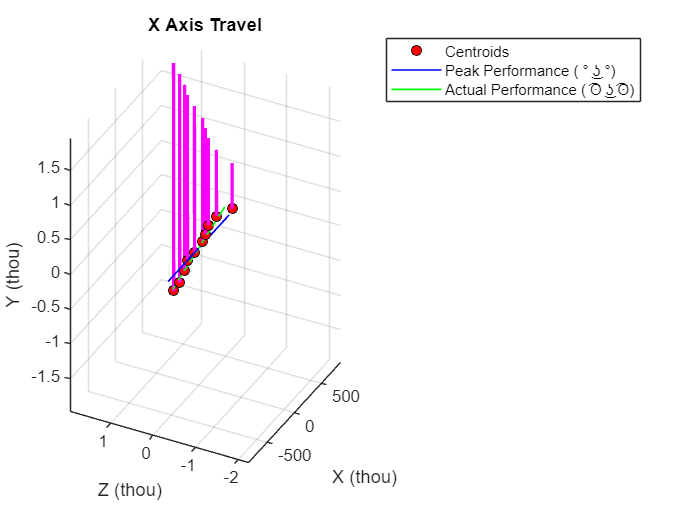

plot_view = "Distorted";
if (plot_view == "Representative")
axis equal   
end
xlabel("X (thou)");
ylabel("Z (thou)");
zlabel("Y (thou)");
if (Axis == "X")
    title("X Axis Travel")
else
    title("Z Axis Travel")
end
%add a little space around the sides
xlim([minX, maxX]*1.5);
ylim([minZ,maxZ]*1.5);
zlim([minY,maxY]*1.5);
legend("Centroids", "Peak Performance ( ° ͜ʖ °)", "Actual Performance ( ͡ʘ ͜ʖ ͡ʘ)")
grid on
hold off

## Numerical Analysis

Let's extract some key information that we can use to inform how to shim this doodad.

Firstly, how straight is the axis?

Let's find the angles between our best fit line axis and each of the principal axes. Ideally these are aligned, with the measured direction angle being zero and the others being perfectly 90 degrees.

x_angle_deg = rad2deg(acos(dot(best_fit_direction, [1,0,0])));
y_angle_deg = rad2deg(acos(dot(best_fit_direction, [0,1,0])));
z_angle_deg = rad2deg(acos(dot(best_fit_direction, [0,0,1])));
fprintf("X (deg): %.3f, Y(deg): %.3f,Z(deg): %.3f", x_angle_deg, y_angle_deg, z_angle_deg)

X (deg): 0.190, Y(deg): 90.133,Z(deg): 89.864

How well does our best fit line fit?

(note that this assumes the centroids are centered around (0,0,0), which they are)

projected_lengths = (centroids*best_fit_direction)./(best_fit_direction'*best_fit_direction);
projected_points = projected_lengths*best_fit_direction';
distance_vectors = centroids-projected_points;
perp_distances = sqrt(sum(distance_vectors.^2,2));
total_variation = sum(sum(centroids.^2));
residual_variation = sum(perp_distances.^2,1);

This R^2 better be damn close to 1

If this is lower than 98% your data is kinda sus, or your lathe is kinda sus, respectfully

R_squared = 1-(residual_variation/total_variation);
fprintf("Your R^2 is a whopping %.10f", R_squared)

Your R^2 is a whopping 0.9999999544